x = [1 2 2.5 3 4 5];
y = [1 5 7 8 2 1];
xx = linspace(1,5,100);
pp = csape(x,y,'second');
% help csape
%csape retunere en struct med coeficienterne til de kubiske funktioner
%der laves en kubiskfunktion imellem hvert punkt
pp.coefs();

% help fnval
yy = fnval(pp,xx); %returnere værdierne af de forskellige polynomier i områderne imellem x værdierne. 
% Hele piecwies funktionen plottes i antal xx værdier man har valgt.


plot(x,y,'bo','DisplayName','data')
hold on

plot(xx,yy,'r','DisplayName','fnval');
xlabel('x'); ylabel('y');
title('Forskellige interpolations metoder')
grid


% help spline

yq = spline(x,y,xx)

yq =     1.0000    1.1397    1.2824    1.4279    1.5761    1.7269    1.8801    2.0356    2.1931    2.3526    2.5138    2.6767    2.8411    3.0068    3.1736    3.3415    3.5102    3.6797    3.8497    4.0201    4.1907    4.3615    4.5322    4.7026    4.8727    5.0423    5.2113    5.3794    5.5465    5.7125    5.8772    6.0405    6.2021    6.3621    6.5201    6.6761    6.8298    6.9812    7.1299    7.2742    7.4121    7.5414    7.6601    7.7661    7.8572    7.9314    7.9866    8.0207    8.0317    8.0173


%Laber cubic spliens ud fra x, y værdier i et interval xx
plot(xx,yq,'g','DisplayName','spline');

Vq = interp1(x,y,xx, 'pchip')

Vq =     1.0000    1.1616    1.3232    1.4848    1.6465    1.8081    1.9697    2.1313    2.2929    2.4545    2.6162    2.7778    2.9394    3.1010    3.2626    3.4242    3.5859    3.7475    3.9091    4.0707    4.2323    4.3939    4.5556    4.7172    4.8788    5.0407    5.2081    5.3817    5.5592    5.7385    5.9176    6.0943    6.2665    6.4321    6.5890    6.7351    6.8683    6.9864    7.0957    7.2074    7.3194    7.4297    7.5362    7.6368    7.7293    7.8117    7.8818    7.9375    7.9767    7.9973


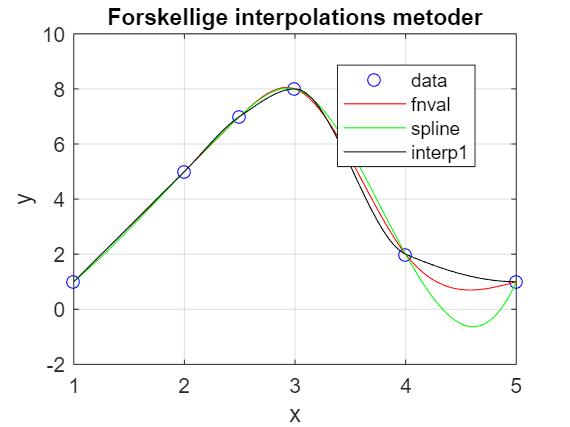

plot(xx,Vq,'k','DisplayName','interp1');

% help interp1 

legend('Location', 'best')

hold off

De tre kurver slutter forskelligt i højre ende, hvor kurven skal ”dreje af”. Not-a-knot splinekurven i (b) har et større ”undersving” end natural splinekurven i (a). Det skyldes, at en natural spline slutter med en andenafledet på nul i endepunkterne (dvs. krumning lig nul), mens en Nota-knot spline slutter med mere generelle tredjegradspolynomier i de to endepunkter. I (c) ses, at en Piecewise Cubic Hermite Interpolation Spline laver de mindste sving af alle i højre ende. Det skyldes, at denne type splines netop er designet til at minimere over- og undersving.

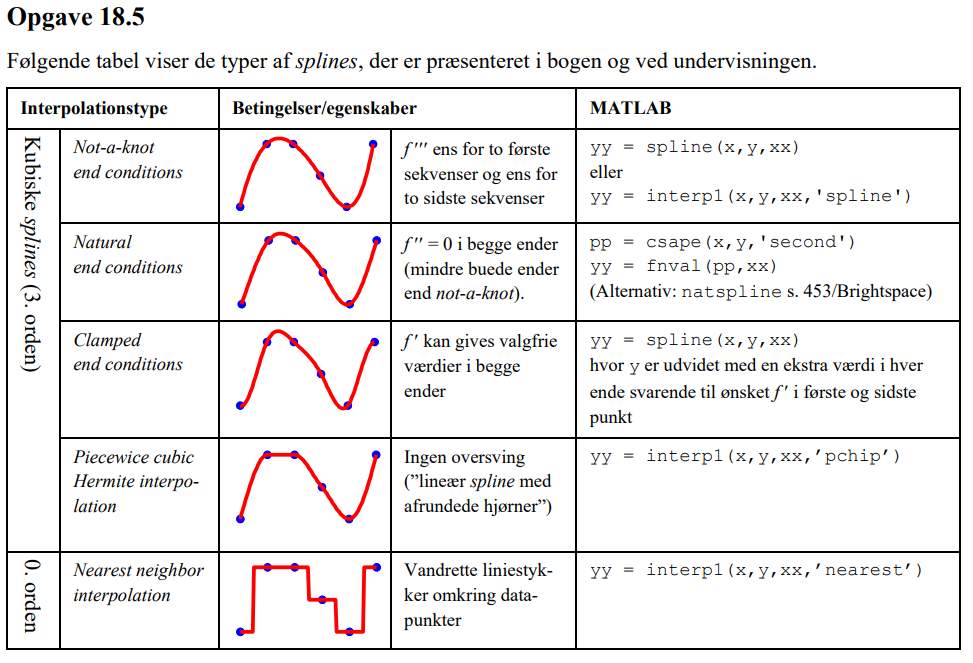

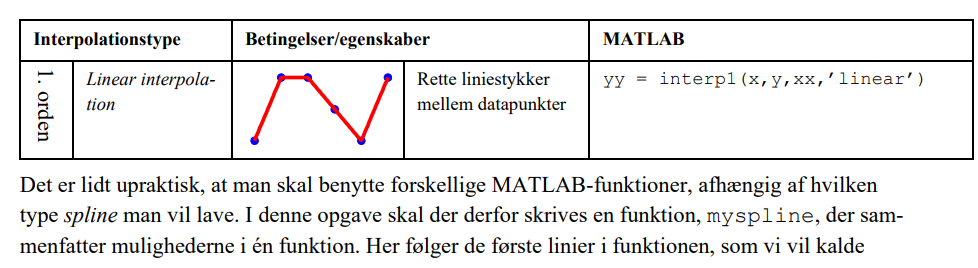

x = [1 2 3 4 5 6];
y = [2 6 4 4 2 6];
xx = linspace(1,6);
yy = myspline(x,y,xx,'not-a-knot');

Error: File: myspline.m Line: 29 Column: 25
Invalid text character. Check for unsupported symbol, invisible character, or pasting of non-ASCII characters.

subplot(3,2,1)

plot(x,y,'o',xx,yy)
title('Not-a-knot end conditions')
yy = myspline(x,y,xx,'natural');
subplot(3,2,2)
plot(x,y,'o',xx,yy)
title('Natural end conditions')
yy = myspline(x,[0 y -2],xx,'clamped');
subplot(3,2,3)
plot(x,y,'o',xx,yy)
title('Clamped end conditions')
yy = myspline(x,y,xx,'pchip');
subplot(3,2,4)
plot(x,y,'o',xx,yy)
title('Piecewise cubic Hermite interpolation')
yy = myspline(x,y,xx,'nearest');
subplot(3,2,5)
plot(x,y,'o',xx,yy)
title('Nearest neighbor interpolation')
yy = myspline(x,y,xx,'linear');
subplot(3,2,6)
plot(x,y,'o',xx,yy)
title('Linear interpolation')